%%%%%%%%%%%%%%%%

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice6'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = 'cConfig.in'; % Nom du fichier d'entree de base

nsimul = 10; % Nombre de simulations a faire

N = linspace(20,200, nsimul);

paramstr = 'N'; % Nom du parametre a scanner
param = N; % Valeurs du parametre a scanner

## Simulations %%

%%%%%%%%%%%%%%%%%

output = cell(1, nsimul); % Tableau de cellules contenant le nom des fichiers de sortie
for i = 1:nsimul
    output{i} = [paramstr, '=', num2str(param(i))];
    % Execution du programme en lui envoyant la valeur a scanner en argument
    cmd = sprintf('wsl %s%s %s N1=%.15g N2=%.15g  output=%s', repertoire, executable, input, param(i) , param(i),output{i});
    disp(cmd)
    system(cmd);
end

wsl ./Exercice6 cConfig.in N1=20 N2=20  output=N=20


	output=N=20
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=20
	N2=20


wsl ./Exercice6 cConfig.in N1=40 N2=40  output=N=40


	output=N=40
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=40
	N2=40


wsl ./Exercice6 cConfig.in N1=60 N2=60  output=N=60


	output=N=60
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=60
	N2=60


wsl ./Exercice6 cConfig.in N1=80 N2=80  output=N=80


	output=N=80
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=80
	N2=80


wsl ./Exercice6 cConfig.in N1=100 N2=100  output=N=100


	output=N=100
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=100
	N2=100


wsl ./Exercice6 cConfig.in N1=120 N2=120  output=N=120


	output=N=120
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=120
	N2=120


wsl ./Exercice6 cConfig.in N1=140 N2=140  output=N=140


	output=N=140
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=140
	N2=140


wsl ./Exercice6 cConfig.in N1=160 N2=160  output=N=160


	output=N=160
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=160
	N2=160


wsl ./Exercice6 cConfig.in N1=180 N2=180  output=N=180


	output=N=180
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=180
	N2=180


wsl ./Exercice6 cConfig.in N1=200 N2=200  output=N=200


	output=N=200
	b=0.06
	R=0.12
	V0=0
	trivial=1
	a0=10000
	trivial=1
	N1=200
	N2=200


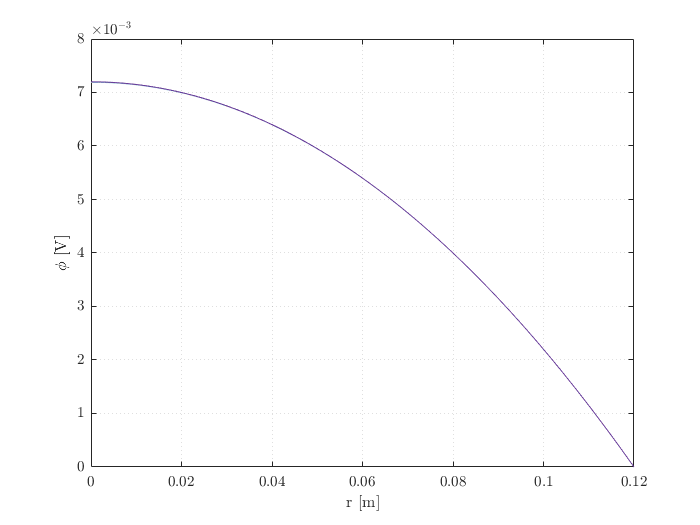

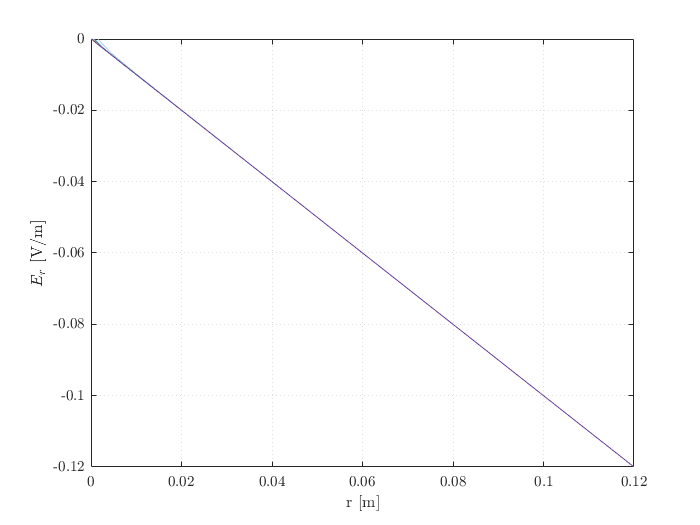

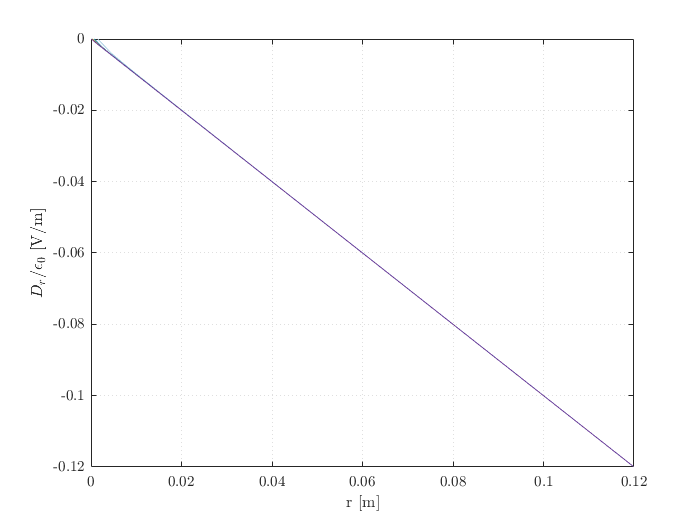

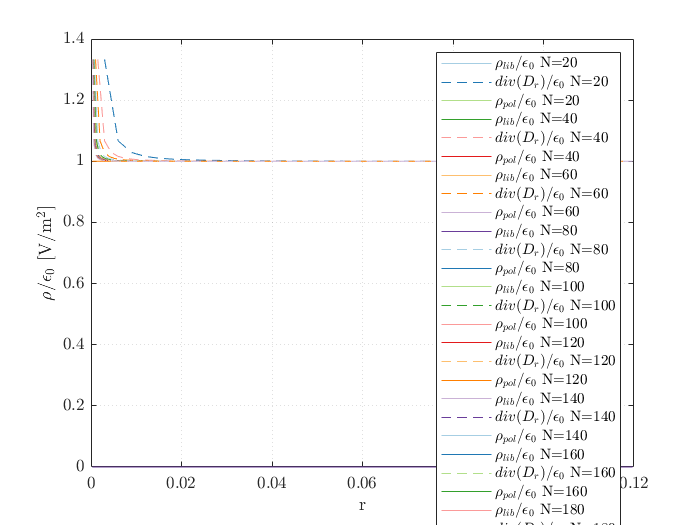


fPhi = figure;
axPhi = axes(fPhi);
hold on
xlabel('r [m]')
ylabel('$\phi$ [V]')
grid on, box on

fEr = figure;
axEr = axes(fEr);
hold on
xlabel('r [m]')
ylabel('$E_r$ [V/m]')
grid on, box on

fDr = figure;
axDr = axes(fDr);
hold on
xlabel('r [m]')
ylabel('$D_r/\epsilon_0$ [V/m]')
grid on, box on

fRho = figure;
axRho = axes(fRho);
hold on
xlabel('r')
ylabel('$\rho/\epsilon_0$ [V/m$^2$]')
legend('show')
grid on, box on


for i = 1:nsimul % Parcours des resultats de toutes les simulations
    
    filename = output{i};
    
    data = load([filename '_Er_Dr.out']);
    rmid = data(:,1);
    Er = data(:,2);
    Dr = data(:,3);
    data = load([filename '_phi.out']);
    r = data(:,1);
    phi = data(:,2);
    data = load([filename '_rholib_divEr_divDr.out']);
    rmidmid = data(:,1);
    rholib = data(:,2);
    divEr = data(:,3);
    divDr = data(:,4);
    
    plot(axPhi,r,phi)
    
    plot(axEr,rmid,Er)
    
    plot(axDr,rmid,Dr)
    
    plot(axRho,rmidmid,rholib,'DisplayName',['$\rho_{lib}/\epsilon_0$ ' filename])
    plot(axRho,rmidmid,-divDr,'--','DisplayName',['$div(D_r)/\epsilon_0$ ' filename])
   plot(axRho,rmidmid,divEr-divDr,'DisplayName',['$\rho_{pol}/\epsilon_0$ ' filename])
    
    
    
    
    
    
end